# Wrap a molecule

First let's import and translate some molecule...

close all;
atom=import_atom('6x4MMT.gro');

Found .gro file
.gro file imported
Elapsed time is 0.014476 seconds.
Looking up bonds
Calculating the distance matrix


ans = 1×1 cell array
    {'Al'}

ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans = 1×1 cell array
    {'Si'}

ans =    960

Composition info:


composition = struct with fields:
     resnames: {'MMT'}
    nresidues: 1
       natoms: 960

Atom_types = 1×4 cell array
    {'Al'}    {'H'}    {'O'}    {'Si'}

Atom_numbers =     96    96   576   192


The box dimensions are:


Box_dim =   31.187999999999999  36.060000000000002  10.000000000000000


The cell dimensions are:


Cell =   31.187999999999999  36.060000000000002  10.000000000000000  90.000000000000000  90.000000000000000  90.000000000000000


Choose between these representations:
ballstick licorice smallvdw halfvdw vdw contour crystal ionic polyhedra lines labels charge index


rmaxlong =    2.250000000000000

Scanning intramolecular bonds, neglecting the PBC
Calculating the distance matrix


ans = 1×1 cell array
    {'Al'}

ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans = 1×1 cell array
    {'Si'}

ans =    960

Elapsed time is 0.329971 seconds.
Drawing the atoms
Elapsed time is 0.228007 seconds.
Drawing the bonds


ans =    100

ans =    200

ans =    300

ans =    400

ans =    500

ans =    600

ans =    700

ans =    800

ans =    900

ans =         1000

ans =         1100

ans =         1200

ans =         1300

Elapsed time is 3.446418 seconds.


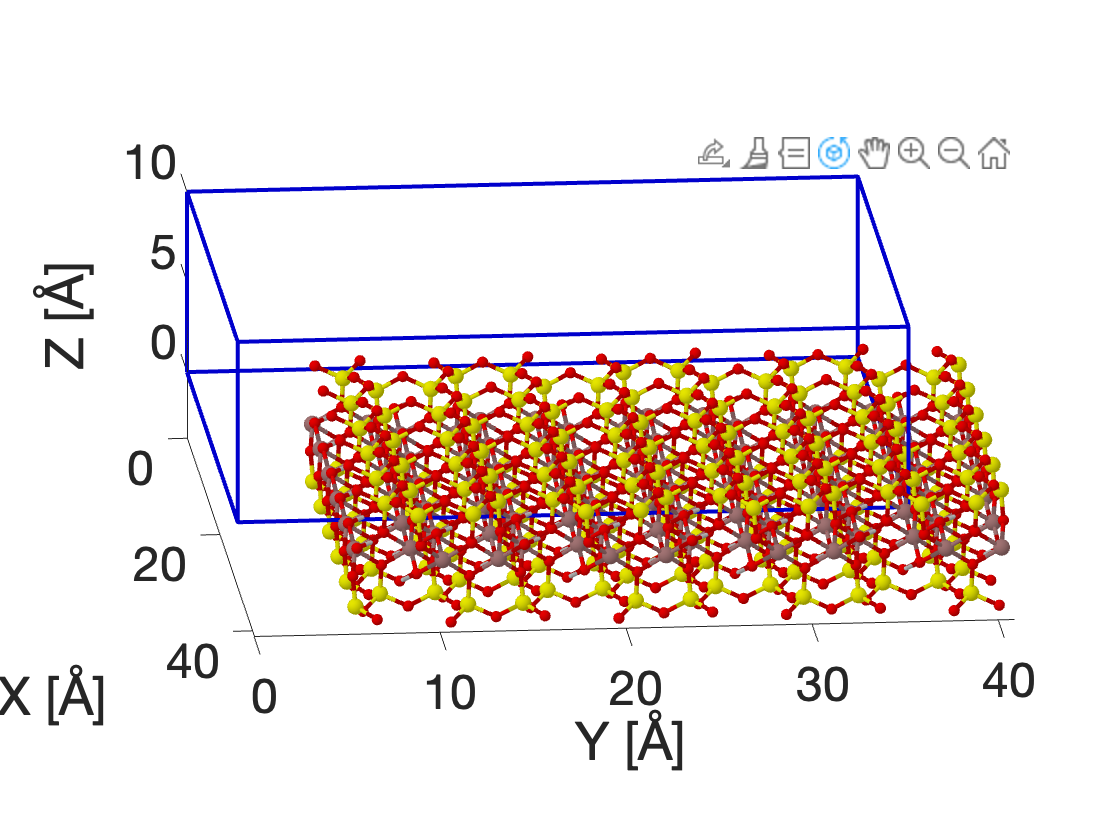

atom=translate_atom(atom,[10 5 -5]); % [10 5 -5] is the translation vector
show_atom(atom,Box_dim); view(85,15)

%vmd(atom,Box_dim)

Let's wrap every atom back into the box!

Choose between these representations:
ballstick licorice smallvdw halfvdw vdw contour crystal ionic polyhedra lines labels charge index


rmaxlong =    2.250000000000000

Scanning intramolecular bonds, neglecting the PBC
Calculating the distance matrix


ans = 1×1 cell array
    {'Al'}

ans = 1×1 cell array
    {'H'}

ans = 1×1 cell array
    {'O'}

ans = 1×1 cell array
    {'Si'}

ans =    960

Elapsed time is 0.310908 seconds.
Drawing the atoms
Elapsed time is 0.222326 seconds.
Drawing the bonds


ans =    100

ans =    200

ans =    300

ans =    400

ans =    500

ans =    600

ans =    700

ans =    800

ans =    900

ans =         1000

Elapsed time is 3.547058 seconds.


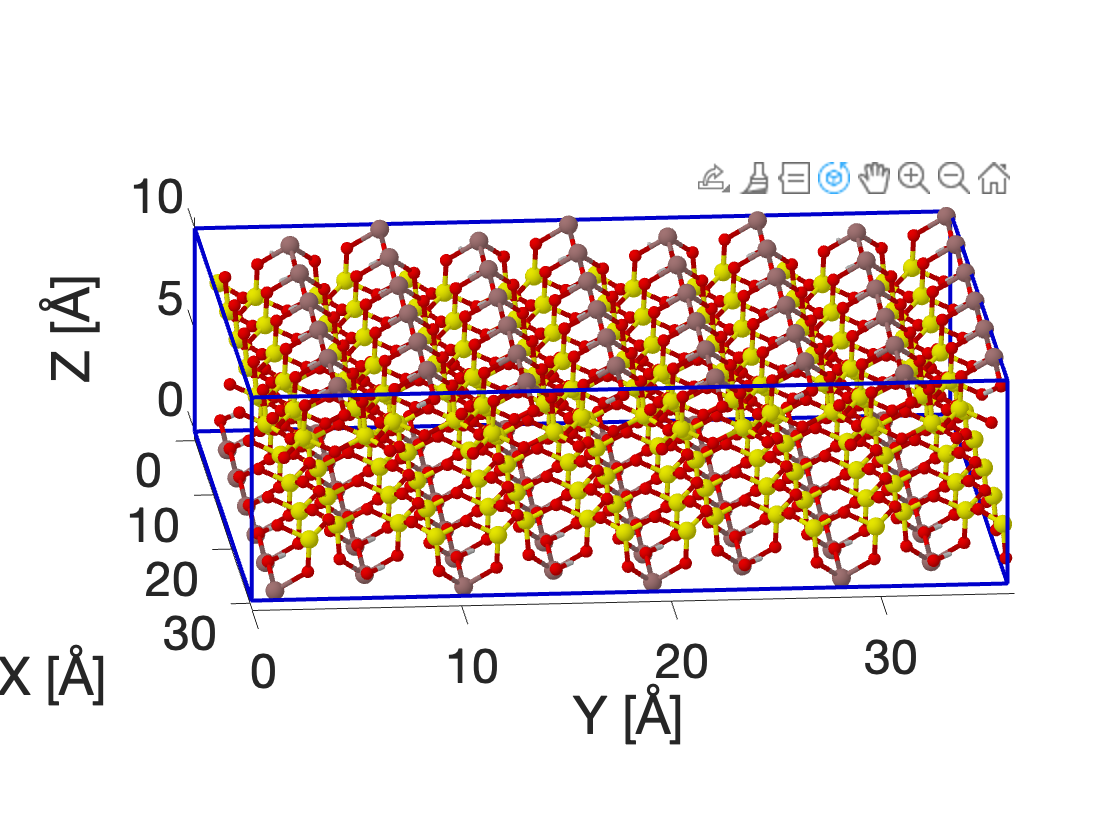

close all;
atom=wrap_atom(atom,Box_dim);
show_atom(atom,Box_dim); view(85,15);

%vmd(atom,Box_dim)